# 03G. Effective potential revisited

## Mingyang Lu

## 1/7/2024

Consider the following system:

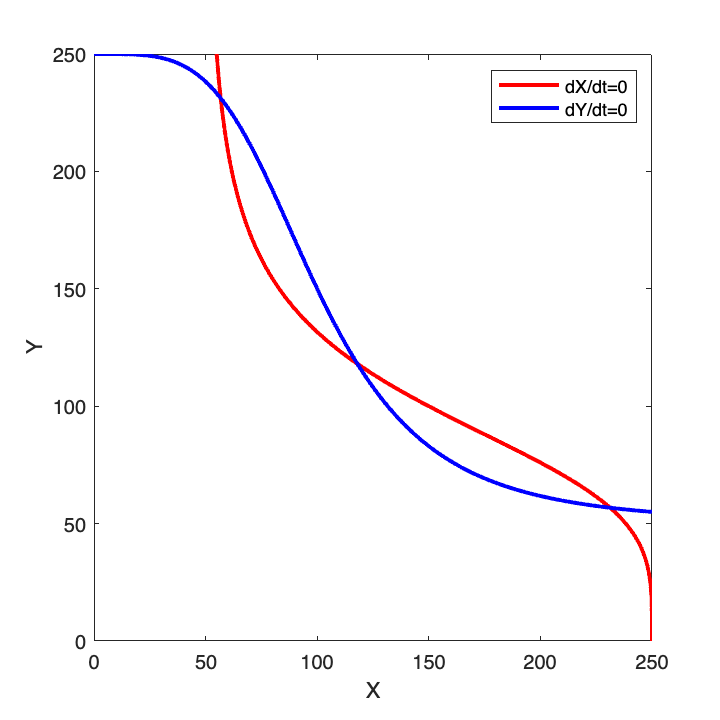

% Set the X and Y ranges
X_range = [0, 250];
Y_range = [0, 250];

% Generate nullclines
null1 = null_fx(20, X_range, Y_range);
null2 = null_fy(20, X_range, Y_range);

% Plot the nullclines
figure('Units', 'inches', 'Position', [0, 0, 5, 5]);
plot(null1(:, 1), null1(:, 2), 'red', ...
    'DisplayName', 'dX/dt=0','LineWidth', 2);
hold on;
plot(null2(:, 1), null2(:, 2), 'blue', ...
    'DisplayName', 'dY/dt=0','LineWidth', 2);

xlabel('X');
ylabel('Y');
legend();
hold off;

We perform the following two calculations.

First, we compute the potential along the first nullcline, $f_X (X,Y)=0$.

$U(X+\Delta x,Y+\Delta y)=U(X,Y)-\frac{f_Y (X,Y)+f_Y (X+\Delta x,Y+\Delta y)}{2}\Delta y$.

Second, we can also compute the potential along the second nullcline, $f_Y (X,Y)=0$. 

$U(X+\Delta x,Y+\Delta y)=U(X,Y)-\frac{f_X (X,Y)+f_X (X+\Delta x,Y+\Delta y)}{2}\Delta x$.

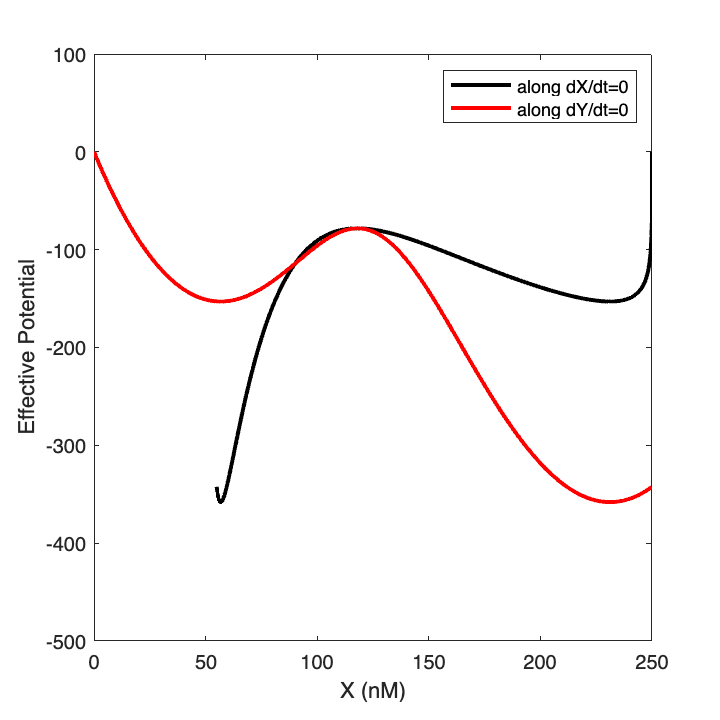

% Integrate along nullclines
U1 = cal_int_2D_line(null1, @derivs_ts);
U2 = cal_int_2D_line(null2, @derivs_ts);

% Plot the results (along X)
figure('Units', 'inches', 'Position', [0, 0, 5, 5]);
plot(U1(:, 1), U1(:, 3), 'black', 'DisplayName', 'along dX/dt=0' ...
    ,'LineWidth', 2);
hold on;
plot(U2(:, 1), U2(:, 3), 'red', 'DisplayName', 'along dY/dt=0' ...
    ,'LineWidth', 2);

xlabel('X (nM)');
ylabel('Effective Potential');
xlim([0, 250]);
ylim([-500, 100]);
legend();
hold off;

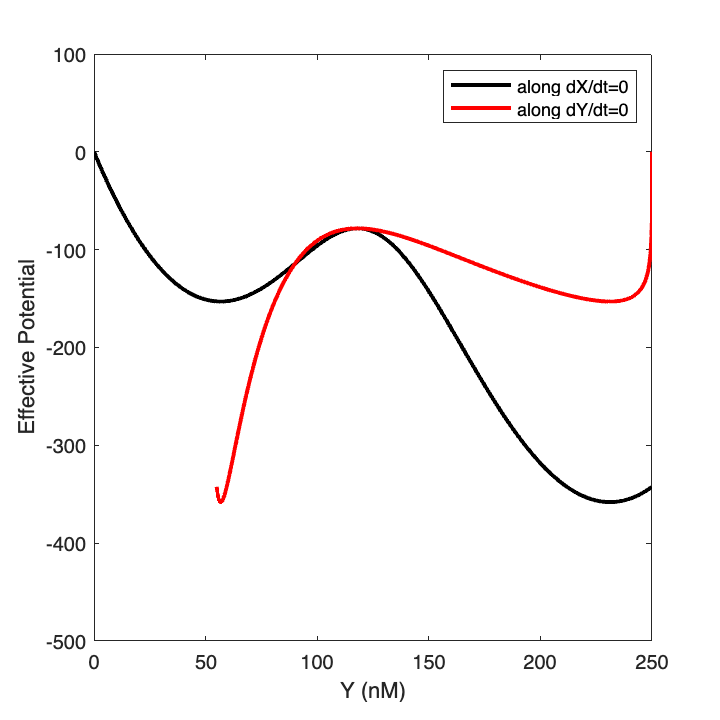


% Plot the results (along Y)
figure('Units', 'inches', 'Position', [0, 0, 5, 5]);
plot(U1(:, 2), U1(:, 3), 'black', 'DisplayName', 'along dX/dt=0' ...
    ,'LineWidth', 2);
hold on;
plot(U2(:, 2), U2(:, 3), 'red', 'DisplayName', 'along dY/dt=0' ...
    ,'LineWidth', 2);

xlabel('Y (nM)');
ylabel('Effective Potential');
xlim([0, 250]);
ylim([-500, 100]);
legend();
hold off;

### Define MATLAB functions

1. Define derviatives function for a toggle swtich circuit

function dXdt = derivs_ts(t, Xs)
    dXdt(1) = 5 + 20 / (1 + (Xs(2) / 100)^4) - 0.1 * Xs(1);
    dXdt(2) = 5 + 20 / (1 + (Xs(1) / 100)^4) - 0.1 * Xs(2);
end

2. Generate nullcline for dX/dt = 0

function results = null_fx(gX, X_range, Y_range)
    Y_all = linspace(Y_range(1), Y_range(2), 1000);
    X_all = (5 + gX ./ (1 + (Y_all ./ 100).^4)) ./ 0.1;
    results = [X_all', Y_all'];
end

3. Generate nullcline for dY/dt = 0

function results = null_fy(gY, X_range, Y_range)
    X_all = linspace(X_range(1), X_range(2), 1000);
    Y_all = (5 + gY ./ (1 + (X_all ./ 100).^4)) ./ 0.1;
    results = [X_all', Y_all'];
end

4. Integrate f = derivs along a line with the trapezoidal rule

function result = cal_int_2D_line(line, derivs)
    ntot = size(line, 1);
    U_all = zeros(ntot, 1);
    X = 0;
    U_all(1) = 0;

    for i = 1:ntot - 1
        dx = line(i + 1, 1) - line(i, 1);
        dy = line(i + 1, 2) - line(i, 2);
        Xs_i = line(i, :);
        Xs_i1 = line(i + 1, :);
        dX_i = derivs(0, Xs_i)';
        dX_i1 = derivs(0, Xs_i1)';

        U_all(i + 1) = U_all(i) - (dX_i(1) + dX_i1(1)) / 2 * dx - (dX_i(2) + dX_i1(2)) / 2 * dy;
    end

    result = [line, U_all];
end
